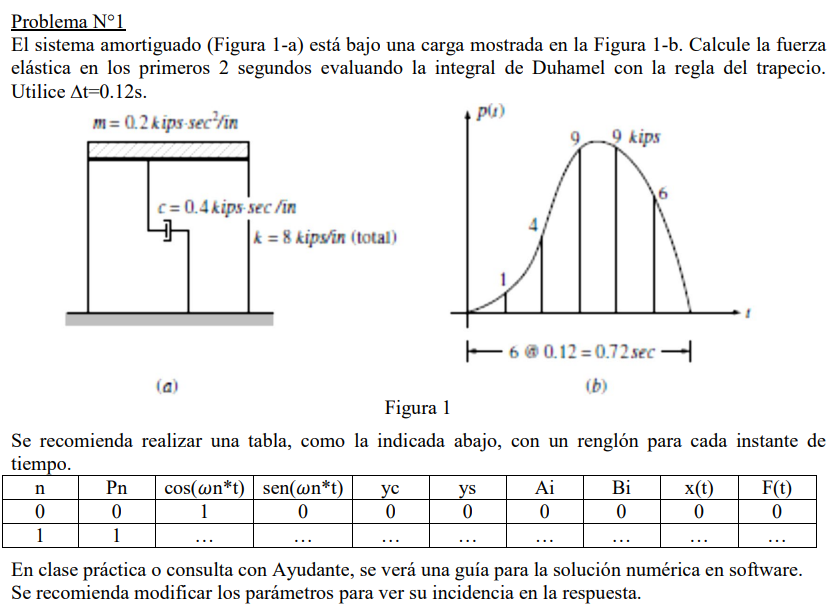

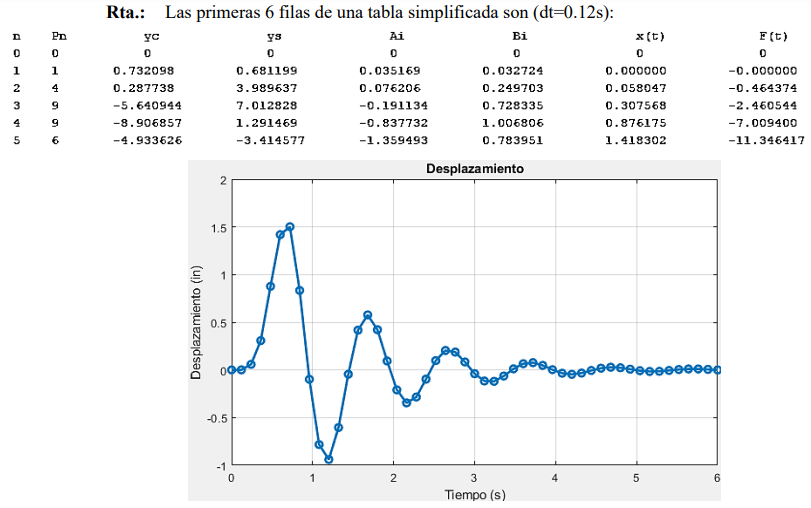

Primero hay que obtener yc e ys:

Luego calculo  los terminos An y Bn para **sistemas amortiguados**:

La misma fórmula se usa para Bn pero usando ys en vez de yc.

Finalmente puedo calcular la respuesta a un sistema amortiguado con condiciones iniciales nulas con:

clc; clear;

dt=0.12;
tf=5;
t=0:dt:tf;

e=exp(1);

%% ---------------PARÁMETROS DEL SISTEMA-----------------------
m=0.2;
c=0.4;
k=8;
w=sqrt(k/m);
zeta = c/(2*m*w);
wd=w*sqrt(1-zeta^2);

%% ------------- DESCRIPCIÓN DE FUERZA EXTERNA ---------------

P=zeros(1,length(t));
P(2)=1; P(3)=4; P(4)=9; P(5)=9; P(6)=6; %Valores datos para los primeros 6 dt

%% ------------ CALCULO INTEGRAL DE DUHAMEL ------------------

yc = P.*cos(w*t); %Se usa en la integral duhamel
ys = P.*sin(w*t); %Se usa en la integral de duhamel

A = zeros(1,length(t)); %Se usa en la integral de duhamel
B = zeros(1,length(t)); %Se usa en la integral de duhamel

for i=2:length(t)
    A(i) = A(i-1)*e^(-zeta*w*dt) + dt/(2*w*m) * (yc(i-1)*e^(-zeta*w*dt) + yc(i));
    B(i) = B(i-1)*e^(-zeta*w*dt) + dt/(2*w*m) * (ys(i-1)*e^(-zeta*w*dt) + ys(i));
end

x = A.*sin(w*t) - B.*cos(w*t);

P

P =      0     1     4     9     9     6     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


yc

yc =          0    0.7256    0.2115   -5.8395   -8.9497   -4.7651         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


ys

ys =          0    0.6882    3.9944    6.8484    0.9505   -3.6461         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


A

A =          0    0.0344    0.0711   -0.2050   -0.8520   -1.3582   -1.4051   -1.2462   -1.1053   -0.9803   -0.8695   -0.7711   -0.6839   -0.6066   -0.5380   -0.4772   -0.4232   -0.3754   -0.3329   -0.2953   -0.2619   -0.2323   -0.2060   -0.1827   -0.1620   -0.1437   -0.1275   -0.1131   -0.1003   -0.0889   -0.0789   -0.0700   -0.0620   -0.0550   -0.0488   -0.0433   -0.0384   -0.0341   -0.0302   -0.0268   -0.0238   -0.0211


B

B =          0    0.0326    0.2474    0.7123    0.9649    0.7229    0.4877    0.4326    0.3837    0.3403    0.3018    0.2677    0.2374    0.2106    0.1868    0.1656    0.1469    0.1303    0.1156    0.1025    0.0909    0.0806    0.0715    0.0634    0.0562    0.0499    0.0442    0.0392    0.0348    0.0309    0.0274    0.0243    0.0215    0.0191    0.0169    0.0150    0.0133    0.0118    0.0105    0.0093    0.0082    0.0073


x

x =          0         0    0.0579    0.3061    0.8696    1.3995    1.4645    0.7841   -0.1430   -0.8007   -0.9181   -0.5518    0.0121    0.4496    0.5691    0.3788    0.0399   -0.2467   -0.3488   -0.2549   -0.0537    0.1314    0.2114    0.1687    0.0508   -0.0673   -0.1266   -0.1100   -0.0420    0.0325    0.0748    0.0708    0.0322   -0.0142   -0.0436   -0.0450   -0.0236    0.0051    0.0250    0.0282    0.0167   -0.0008


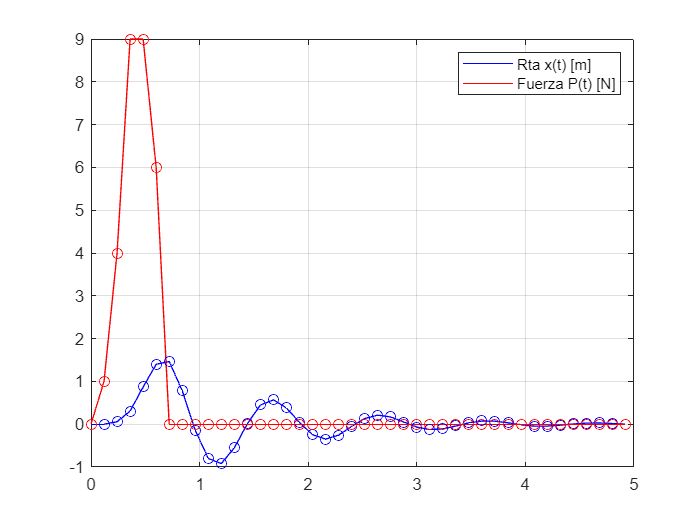


plot(t,x,'b', t,P,'r');
hold on
scatter(t,x,'b');
hold on
scatter(t,P,'r');
hold off
grid on
legend('Rta x(t) [m]', 'Fuerza P(t) [N]');

%hold on
%scatter(t,P,'r');




